clc
clear all
close all

%Importing Data
%Baseline
Baseline= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_Baseline_sorted.txt');
%1Hz_0.2Mpa
Slow= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_1Hz_0p2_sorted.txt');
%1Hz_0.1Mpa
Fast= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_1Hz_0p1_sorted.txt');
%0.1Hz_0.2Mpa
p1= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_0p1Hz_0p2_sorted.txt');
%Making a matrix to store all data
a= length(Baseline)+length(Slow)+length(Fast)+length(p1);
Data= nan(a,7);

Peak Density over time: When is the peak occuring


Data(1:length(Baseline),1)= Baseline(:,2)*1.5;
Data(1:length(Slow),2)=Slow(:,2)*1.5;
Data(1:length(Fast),3)=Fast(:,2)*1.5;
Data(1:length(p1),4)=p1(:,2)*1.5;

Data(Data==0) = NaN;
a=(min(Data))

a =     9.0000    9.0000    4.5000    9.0000       NaN       NaN       NaN


mean(a(2:7))

ans = NaN

std(a(2:7))

ans = NaN

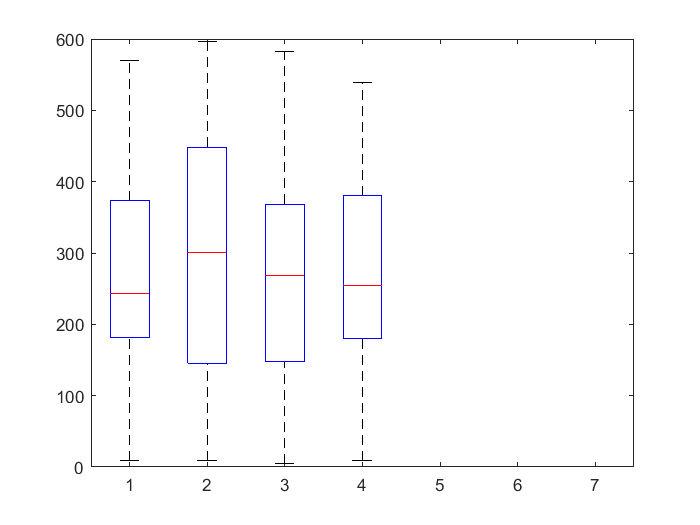

boxplot(Data)
ylim([0 600])

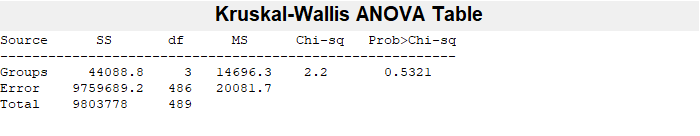

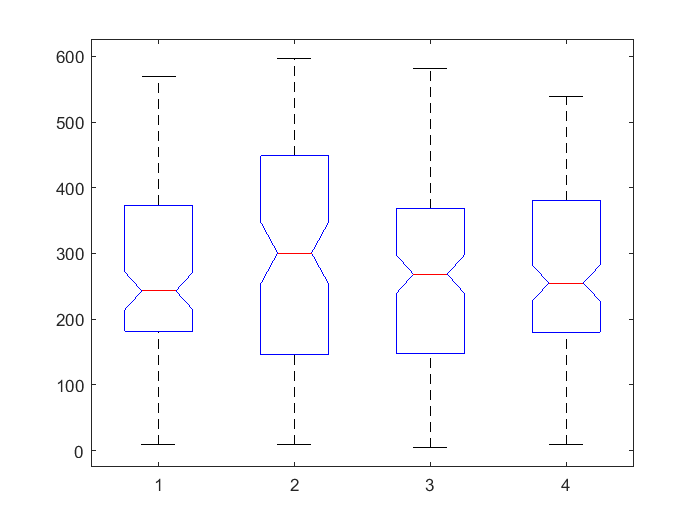

[p,tbl,stats] = kruskalwallis(Data);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


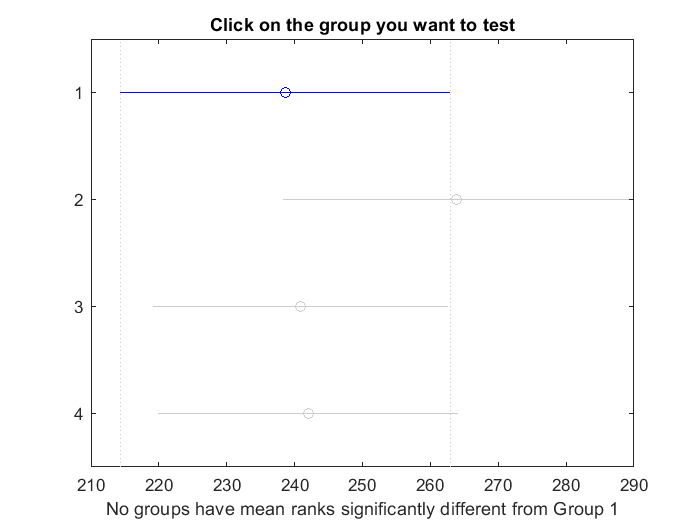

[c,m,h,gnames] = multcompare(stats,'ctype', 'hsd'); %pvalues, means and SE, figurehandles, groupnames

Time between peaks

k=1;
for i=1:length(Baseline)
    if Baseline(i,7)>=2
        Baselinet2p(k)= Baseline(i,9)-Baseline(i,2);
        k=k+1;
        
    end
end
k=1;
for i=1:length(Slow)
    if Slow(i,7)>=2
        Slowt2p(k)= Slow(i,9)-Slow(i,2);
        k=k+1;
    end
end
k=1;
for i=1:length(p1)
    if p1(i,7)>=2
        p1t2p(k)= p1(i,9)-p1(i,2);
        k=k+1;
        if p1(i,7)>=3
            p1t2p(k)= p1(i,16)-p1(i,9);
            k=k+1;
        end
    end
end
k=1;
for i=1:length(Fast)
    if Fast(i,7)>=2
        Fastt2p(k)= Fast(i,9)-Fast(i,2);
        k=k+1;
                if Fast(i,7)>=3
            Fastt2p(k)= Fast(i,16)-Fast(i,9);
            k=k+1;
        end
    end
end


a= length(Baselinet2p)+length(Slowt2p)+length(Fastt2p)+length(p1t2p);
Data= nan(a,7);
Data(1:length(Baselinet2p),1)= Baselinet2p(1,:)*1.5;
Data(1:length(Slowt2p),2)=Slowt2p(1,:)*1.5;
Data(1:length(Fastt2p),3)=Fastt2p(1,:)*1.5;
Data(1:length(p1t2p),4)=p1t2p(1,:)*1.5;

Data(Data==0) = NaN;
Data=rmoutliers(Data);
Data=rmoutliers(Data);
Data=rmoutliers(Data);

a=mean(nanmean(Data))

a = NaN

nanstd(nanmean(Data))

ans = 49.7344

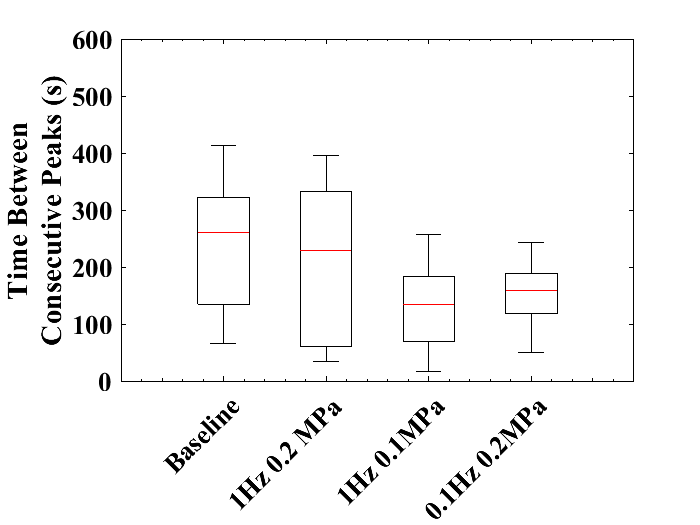

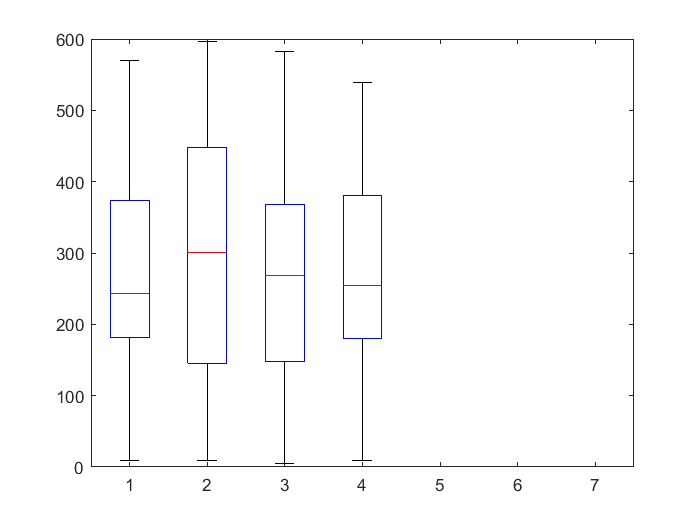


figure1=figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
boxplot(Data,'Colors','k','symbol', '')%,'Orientation',"horizontal")
ylim([0 600])
ylabel({"Time Between"; "Consecutive Peaks (s)"})
xticks([1 2 3 4 5 6 7])
xlim([0 5])
xticklabels({'Baseline','1Hz 0.2 MPa','1Hz 0.1MPa','0.1Hz 0.2MPa'})
xtickangle(45)
h=findobj('LineStyle','--'); set(h, 'LineStyle','-');
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'r');
% Create xlabel
%xlabel('Loading Conditions','FontWeight','bold','FontName','Times New Roman','FontSize',12);
box(axes1,'on');
set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
    'FontSize',16,'FontWeight','bold','YColor',[0 0 0],'XTick',[1 2 3 4],...
    'XTickLabel',{'Baseline','1Hz 0.2 MPa','1Hz 0.1MPa','0.1Hz 0.2MPa'},'XColor',[0 0 0],'XMinorTick',...
    'on','ZColor',[0 0 0]);
% % Change the renderer to "Painters"
set(gcf, 'Renderer', 'Painters')
% 
% % Save the plot as a PNG image
print('Dist_bet_Peaks.png','-dpng', '-r300')

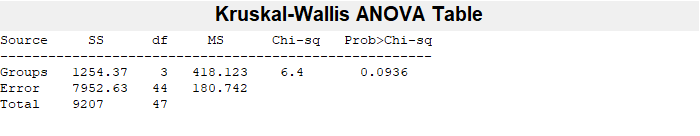

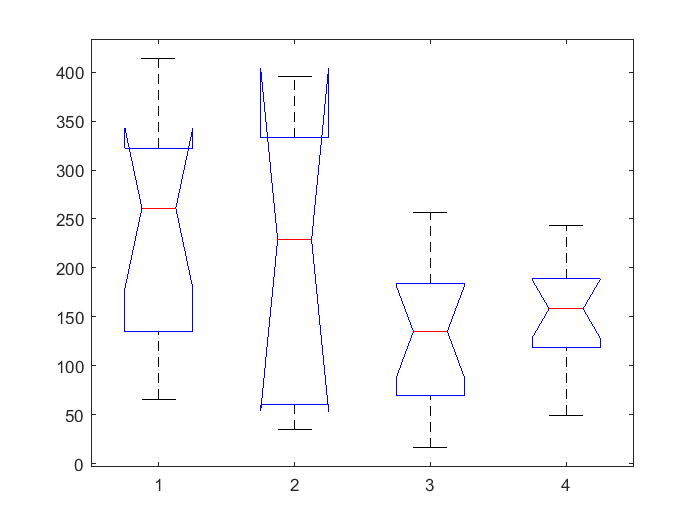

[p,tbl,stats] = kruskalwallis(Data);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


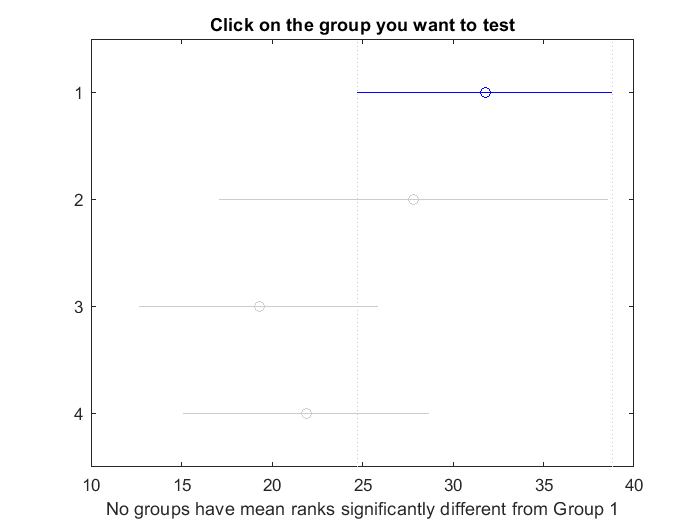

[ct2p,m,h,gnames] = multcompare(stats,"CType","tukey-kramer"); %pvalues, means and SE, figurehandles, groupnames